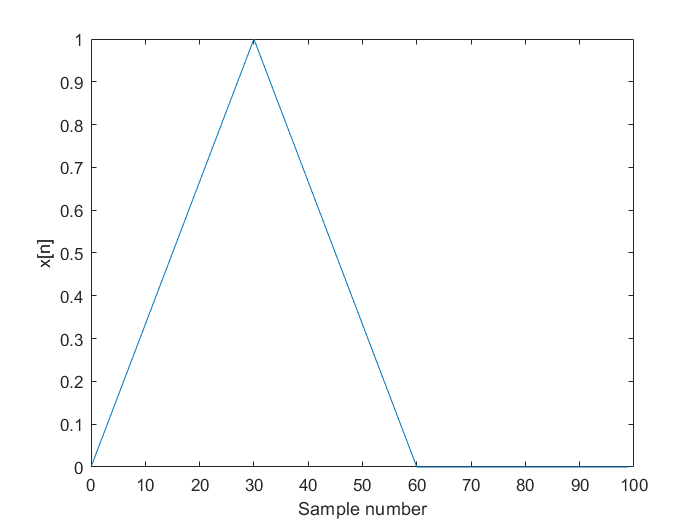

clear all;
close all;
clc;

x = 0:99;
y = (30 - abs(x-30)) / 30;
y(61:100) = 0;
plot(x,y);
xlabel('Sample number');
ylabel('x[n]')

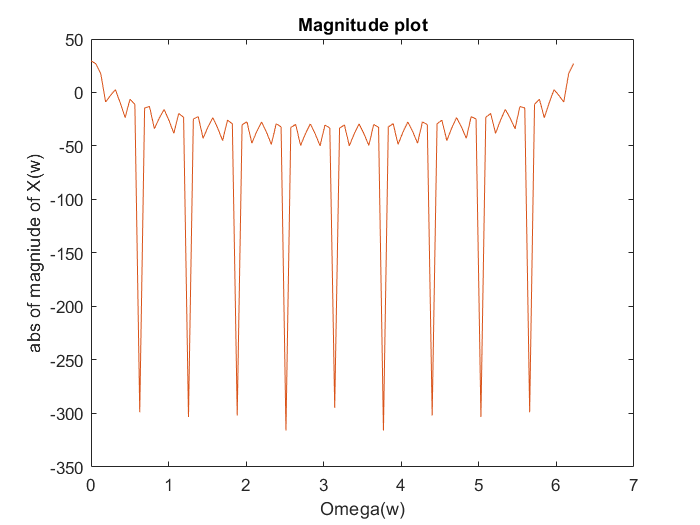


% Plot the fft of triangle directly.
L = length(y);
Xw = fft(y);
Omega = 0:pi/50:99/50*pi;
plot(Omega, mag2db(abs(Xw)));
xlabel('Omega(w)');
ylabel('abs of magniude of X(w)');
title('Magnitude plot');
hold on;

% Plot the fft of the signal by user-defined function.
fft_by_function = realFFT(y);
plot(Omega, mag2db(abs(fft_by_function)));

function fft_final_result = realFFT(signal_input)
% Assume the length of the signal, N, is an even integer.

% 1. Decompse the signal to two parts, even index part and odd index part.
index_even = 1;
index_odd = 1;
N = length(signal_input);
signal_even_part = zeros(1, N/2);
signal_odd_part = zeros(1, N/2);
for i = 1:2:N-1
    signal_even_part(index_even) = signal_input(i);
    index_even = index_even + 1;
end
for m = 2:2:N
    signal_odd_part(index_odd) = signal_input(m);
    index_odd = index_odd + 1;
end

% 2. Build function v[n] = x[n] + j*y[n], where x[n] is the even part of the
% input signal, y[n] is the odd part of the input signal.
v = signal_even_part + j * signal_odd_part;

% 3. Use the method in Exercise 4.1 to get fft of x[n] and y[n] by only
% computing the fft of v[n].
fft_for_v = fft(v);
conjucate_temp = [fft_for_v(1), fft_for_v(end:-1:2)];
fft_for_x = (fft_for_v + conj(conjucate_temp)) / 2;  % FFT for the even part of the input signal.
fft_for_y = (fft_for_v - conj(conjucate_temp)) / (2*j); % FFT for thr odd part of the input signal.

% 4. Use the method specified in Exercise 3.1 to get the final FFT of the
% whole input signal.
k = 0:N-1;
fft_final_result = [fft_for_x, fft_for_x] + exp((-j)*2*pi*k / N).*[fft_for_y, fft_for_y];
end